# EG-247 Signals and Systems: Lab 01: Elementary Signals

This script file demonstrates the use of the `heaviside` and `dirac` functions. To run the code select the commands in the cells.

## The Unit Step Function

In the notes we define the unit step function as


$${u_0}(t) = \left\{ {\begin{array}{*{20}{c}}{0\quad t < 0}\\{1\quad t > 0}\end{array}} 
\right.$$


In MATLAB the unit step is defined using the `heaviside` function. The command  `doc heaviside` will open the documentation for this function in your web browser or a separate documentation window if you're using the desktop MATLAB application.

doc heaviside

Note how the documentation provides a summary of the `heaviside` function but also has interactive code that you can execute.

It's always a good idea to peruse the documentation for any new functions that you encounter. As the documentation pages are just web pages, it's also useful to bookmark the useful ones.

## Using the Symbolic Math Toolbox

The `heaviside` function is part of the [Symbolic Math Toolbox](https://uk.mathworks.com/help/symbolic/index.html) which we will be using a lot in this module. 

We first need to define `t` as a symbol:

syms t;

We can then define and plot the unit step $u_0 \left(t\right)$ by *aliasing* the `heaviside` function with the command:

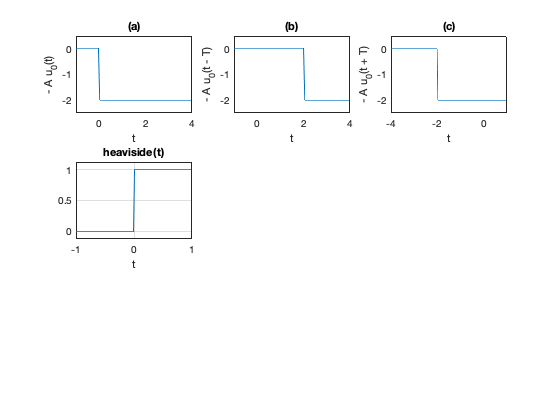

u0(t) = heaviside(t);
ezplot(u0(t),[-1,1]),grid

If we are only interested in the value of the function at a particular instant of time we can pass a number as the argument:

[u0(-1),u0(0),u0(1)]

$$ans = \left(\begin{array}{ccc} 0 & \frac{1}{2} & 1 \end{array}\right)$$

Note that `heaviside(0)` returns the value $1/2$ which is not mathematically correct. As we discussed in class, the unit step function $u_o(t)$ is undefined at $t=0$.

Once you have set things up and defined numerical values of the variables, the basic signal operations work as you'd expect:

A = 2; T = 2;
x0(t) = A * u0(t - T);

And we can plot the signal using the `ezplot` function and label the graph using the `title`, `xlabel` and `ylabel` commands.

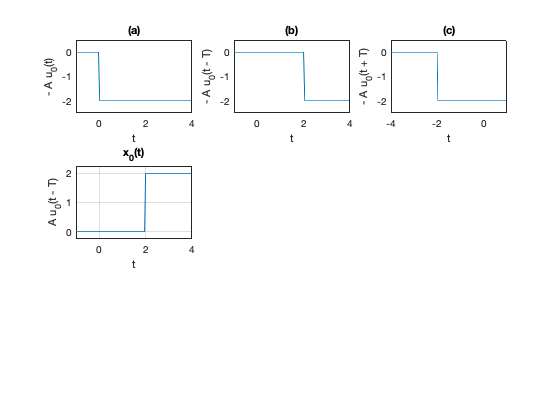

ezplot(x0(t), [-1, 4]),grid
title('x_0(t)'),xlabel('t'),ylabel('A u_0(t - T)')

## Exercise 1

Reproduce Figure 1.8 from the textbook Karris (page 1-4) in MATLAB:

Use the `heaviside`, `subplot`, and `ezplot` functions to plot each of the following on a 3x3 grid:

- 
$$x_1(t) = -Au_0(t)$$


- 
$$x_2(t) = -Au_0(t-T)$$


- 
$$x_3(t)=-Au_0(t+T)$$


- 
$$x_4(t) = Au_0(-t)$$


- 
$$x_5(t) = Au_0(-t+T)$$


- 
$$x_6(t) = Au_0(-t-T)$$


- 
$$x_7(t) = -Au_0(-t)$$


- 
$$x_8(t)=-Au_0(-t+T)$$


- 
$$x_9(t)=-Au_0(-t-T)$$


We have done the first row of the figure for you.

*Hint*: You will need to adjust the axes of each subplot to ensure that the step function is clearly visible. Compare your results with Figure 1 and tweek your settings until your graph looks right. Solution We'll do the first couple of entries for you.


$$x_1(t) = -Au_0(t)$$


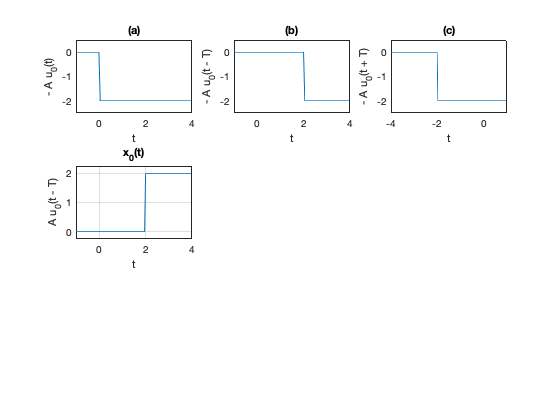

subplot(3,3,1)
x1(t) = - A * u0(t);
ezplot(x1(t), [-1, 4, -2.5, 0.5])
title('(a)'),ylabel('- A u_0(t)'),xlabel('t')


$$x_2(t) = -Au_0(t-T)$$


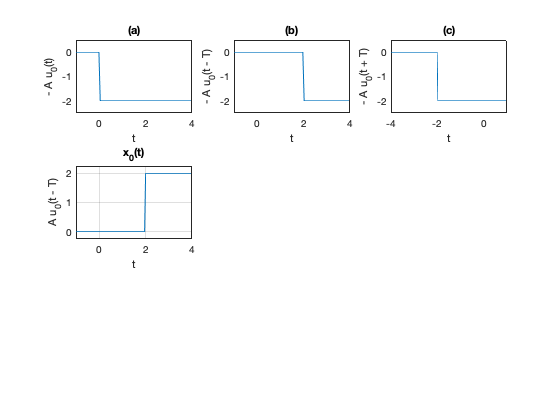

subplot(3,3,2)
x2(t) = - A * u0(t - T);
ezplot(x2(t), [-1, 4, -2.5, 0.5])
title('(b)'),ylabel('- A u_0(t - T)'),xlabel('t')

$$x_3(t)=-Au_0(t+T)$$ remove comments

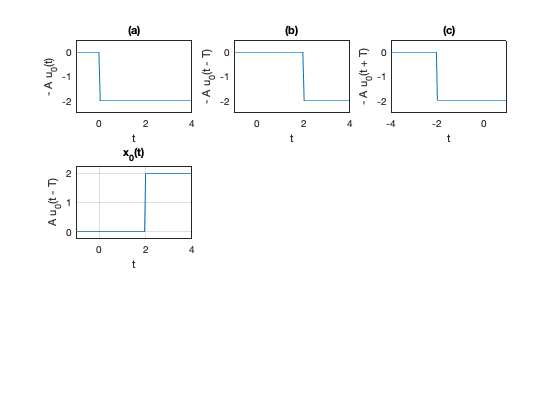

subplot(3,3,3)
x3(t) = - A * u0(t + T);
ezplot(x3(t), [-4, 1, -2.5, 0.5])
title('(c)'),ylabel('- A u_0(t + T)'),xlabel('t')

## Complete the picture


$$x_4(t) = Au_0(-t)$$


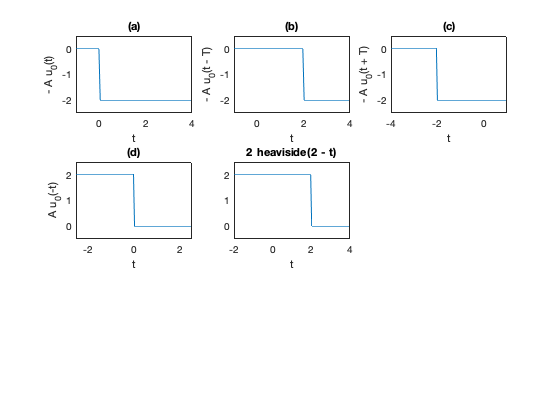

subplot(3,3,4)
x4(t) = A * u0(-t);
ezplot(x4(t), [-2.5, 2.5, -0.5, 2.5])
title('(d)'),ylabel('A u_0(-t)'),xlabel('t')


$$x_5(t) = Au_0(-t+T)$$


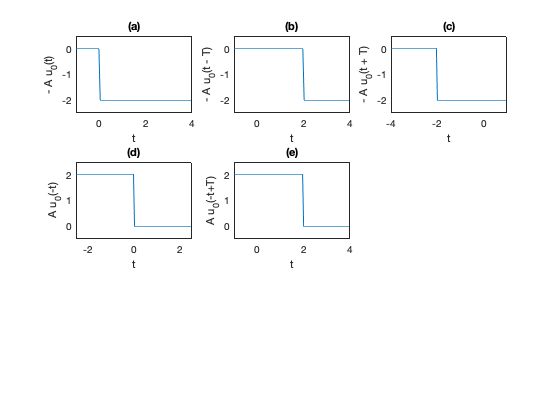

subplot(3,3,5)
x5(t) = A * u0(-t + T);
ezplot(x5(t), [-1, 4, -0.5, 2.5])
title('(e)'),ylabel('A u_0(-t+T)'),xlabel('t')


$$x_6(t) = Au_0(-t-T)$$


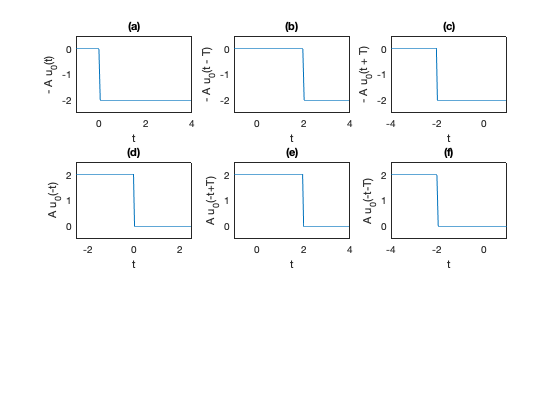

subplot(3,3,6)
x6(t) = A * u0(-t - T);
ezplot(x6(t), [-4, 1, -0.5, 2.5])
title('(f)'),ylabel('A u_0(-t-T)'),xlabel('t')


$$x_7(t) = -Au_0(-t)$$


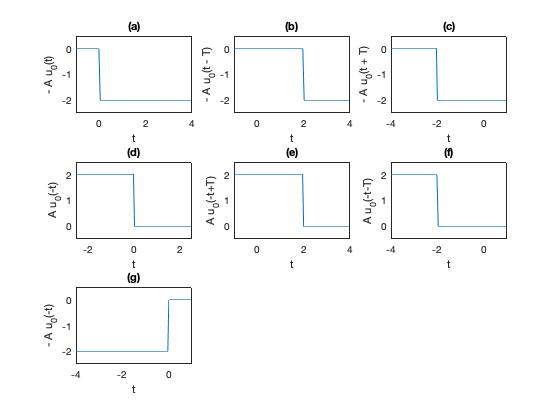

subplot(3,3,7)
x7(t) = - A * u0(-t);
ezplot(x7(t), [-4, 1, -2.5, 0.5])
title('(g)'),ylabel('- A u_0(-t)'),xlabel('t')


$$x_8(t)=-Au_0(-t+T)$$


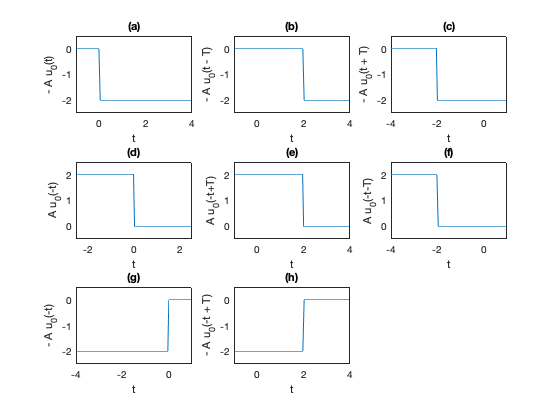

subplot(3,3,8)
x8(t) = - A * u0(-t + T);
ezplot(x8(t), [-1, 4, -2.5, 0.5])
title('(h)'),ylabel('- A u_0(-t + T)'),xlabel('t')


$$x_9(t)=-Au_0(-t-T)$$


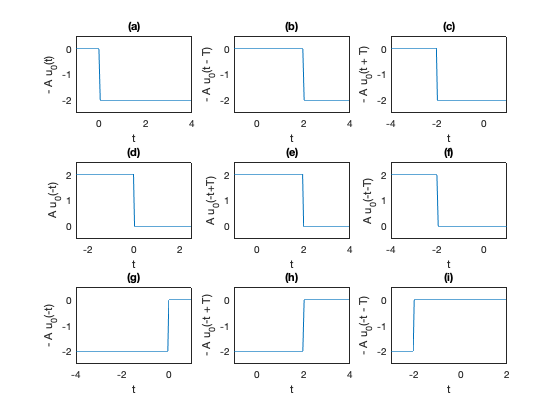

subplot(3,3,9)
x9(t) = - A * u0(-t - T);
ezplot(x9(t), [-3, 2, -2.5, 0.5])
title('(i)'),ylabel('- A u_0(-t - T)'),xlabel('t')